# **Molecular representations and molecular descriptors**

## 1. SMILES strings

The simplified molecular input line-entry system (SMILES) is a specification in the form of a line notation for describing the structure of one or more molecules, using short ASCII strings. SMILES strings can be imported by most molecule editors for conversion back into two-dimensional drawings or three-dimensional models of the molecules.

In brief (Figure 1)

- Atoms are represented by their atomic symbols, with the possibility to omit H; 

- Single, double, triple and aromatic bonds can be represented with the following symbols: “−”, “=”, “#”, and “:”, respectively. Single bonds can be omitted.

- Branches are specified by enclosures in parentheses; 

- Cyclic structures are represented by breaking one single or aromatic bond in each ring and starting from one of the ring atoms. Ring “opening”/”closure” bonds are then indicated by a digit immediately following the atomic symbol at each ring closure. Aromaticity on carbon atoms can be written with lower-case letters or by alternating single and double bonds (Kekulé notation). For instance, benzene can be both written as “c1ccccc1” and “C1=CC=CC=C1”;

- Local chirality can be specified using the symbols “/” and “\”. For instance, E- and Z-1,2-difluoroethene can be written as F/C=C/F and F/C=C\F, respectively. Additionally, tetrahedral centers are often indicated using “@” (or “@@”), following the atomic symbol of the chiral atom. “@” indicates that  the listed neighbors are arranged anticlockwise, while “@@” that they appear in a clockwise order. 

- The chosen atom order for generating the SMILES does not affect the encoded 2D structure. However, several types of standardized (also known as canonicalized) SMILES generation procedures exist.

You can find a summary of SMILES theory here: [https://www.daylight.com/dayhtml/doc/theory/theory.smiles.html](https://www.daylight.com/dayhtml/doc/theory/theory.smiles.html) 

#### 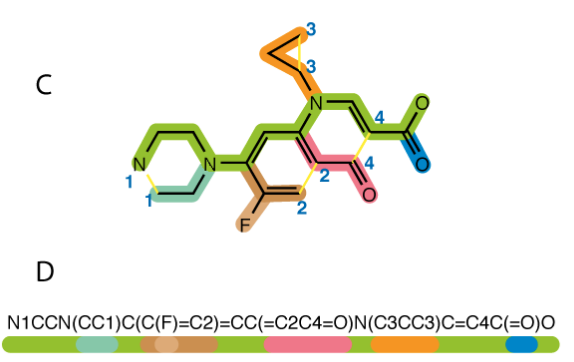

**Figure 1. **Example of the calculation of a SMILES string. Image from [https://chejunkie.com/knowledge-base/convert-cas-registry-number-other/](https://chejunkie.com/knowledge-base/convert-cas-registry-number-other/) 

### Exercise 1

Which of the following molecular depictions (A, B, C, D) corresponds to the reported SMILES string?

**1.1.** SMILES: "`CCCCO`"

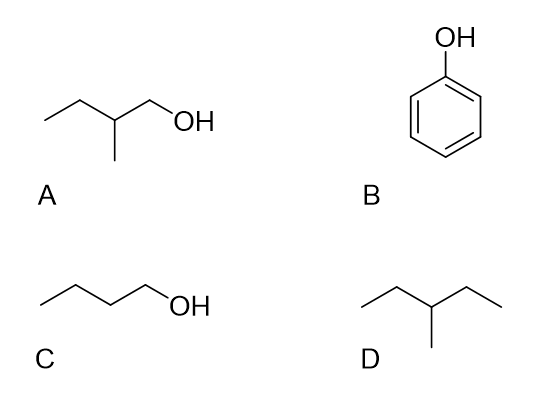

Your response:

""

ans = ""

______________________________________________________

**1.2.** SMILES: "`C1=CC=CC=C1`"

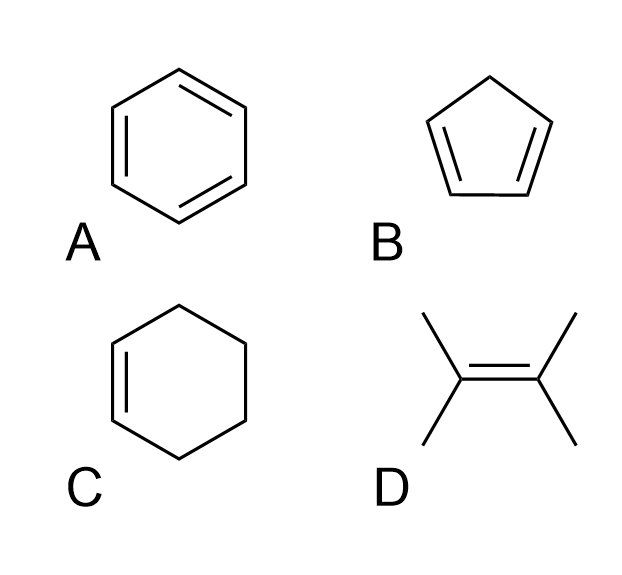

Your response:

""

**1.3.** SMILES: "`FC(F)(F)C1=CC=C(OC)C=C1`"

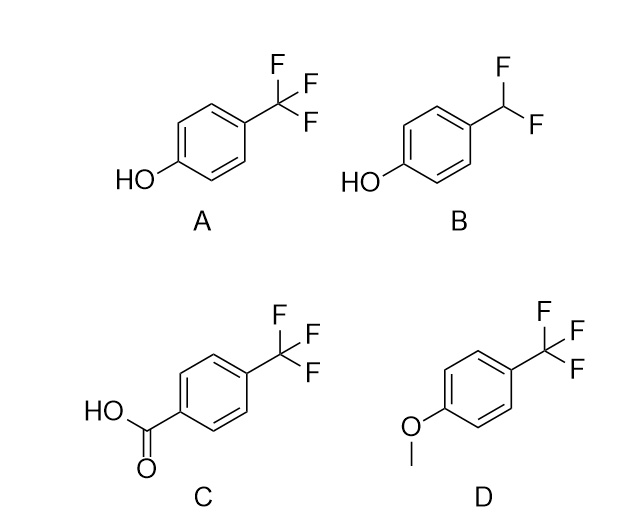

Your response:

""

### Exercise 2

Write a SMILES string for the corresponding molecule (ibuprofen)

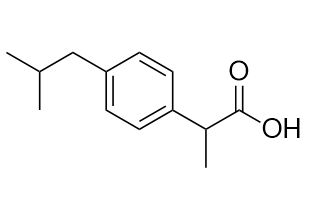

Your SMILES string:

""

====================================================================

## 2. Molecular descriptors 

Molecular descriptors are numbers that capture different aspects of the chemical structure.

Molecular descriptors are obtained:

- From a given molecular representation

- By applying a pre-defined algorithm

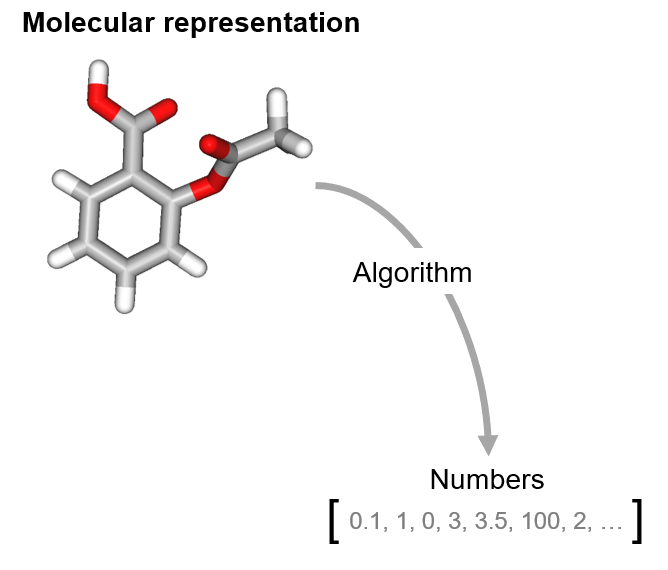

Now that you have understood how to transform any molecule into a SMILES string (your representation!), you will have the occasion to compute your first set of molecular descriptors.

### 2.1. Real-valued descriptors

#### Exercise 1: your first molecular descriptors

Calculate molecular descriptors for two molecules, expressed as SMILES strings:

Molecule 1:

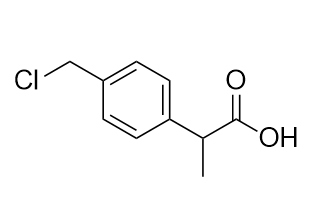

SMILES string: "`ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O`"

Molecule 2:

 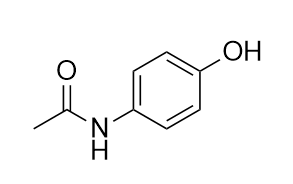

SMILES string: "`CC(=O)Nc1ccc(O)cc1`"

Complete the code below, to compute the following descriptors:

- "nO": number of oxygens

- "nCl": number of chlorine atoms

- "nC": number of carbon atoms

- "nN": number of nitrogen atoms

Tip!

`    strfind(string,refstring) `

finds the occurrence of "`refstring" `in "`string"`. 

Type "`help strfind"` to know more!

**Complete now the code below:**

smi1 = 'ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O';

nO = []; % number of oxygen atoms
nCl = [];  % number of chlorine atoms
nC = []; % number of carbon atoms
nN = []; % number of nitrogen atoms

**Now do the same for this next molecule:**

smi2 = 'CC(=O)Nc1ccc(O)cc1';

nO = []; % number of oxygen atoms
nCl = [];  % number of chlorine atoms
nC = []; % number of carbon atoms
nN = []; % number of nitrogen atoms

Attention: Note how the aromatic carbons are annotated in the two molecules. Is your code stable in case of both "C" and "c"? Also, note that the letter "C" is contained in both carbons ("C") and chlorine atoms ("Cl"); does your code account for that? If not, revise. 

N.B. the uppercase/lowercase flexibility holds for all the aromatic atoms (e.g., nitrogen). Did you think about it? If not, revise again ;) 

#### Exercise 2: descriptor calculation function

The code can be now turned into a function, taking the SMILES as input and providing the descriptors as output (1 x 4, array). Open the empty script called "[compute_count_descriptors.m](matlab:open('compute_count_descriptors.m'))" (current folder) and edit following the tips contained there. 

Now you can use this function to compute the descriptors for any molecule provided as input

[descriptors, labels] = compute_count_descriptors('ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O');

The function you now created can be used to compute the same descriptors for a list of molecules expressed as SMILES. 

You can check whether your code works. Running it on the following SMILES ("FC(F)(F)C1=NC=C(Cl)C=C1"), should provide you with these descriptors:

Try it out for yourself:

[descriptors, labels] = compute_count("FC(F)(F)C1=NC=C(Cl)C=C1")

Did everything work out as planned?

=====================================================================================================

## 3. Molecular similarity

In this part of the exercise, we will compute the molecular similarity between two molecules, using the descriptors you previously computed. 

In particular, we will use three types of distance measures:

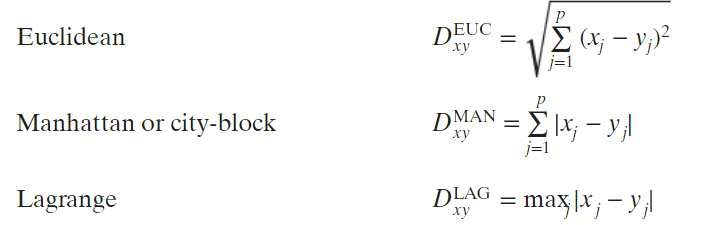

where* j* runs over the *p *molecular descriptors of molecule *x* and molecule *j. *

#### Exercise 1: Euclidean distance

Using your molecular descriptors code, compute the **Euclidean distance** between the two following molecules:

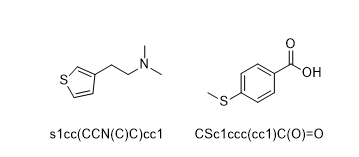

**N.B.** Now that you have learnt how to read/write SMILES strings, I can let you know that you can use several tools to visualize them, e.g.: [http://hulab.rxnfinder.org/smi2img/](http://hulab.rxnfinder.org/smi2img/) 

Complete the code below:

smi_x = "s1cc(CCN(C)C)cc1";
smi_y = "CSc1ccc(cc1)C(O)=O";

[x, labels] = compute_count(smi_x);
% complete your code here
D_e = []; % placeholder for the Euclidean distance

What is the Euclidean distance between the two selected molecules?

""

#### Exercise 2: Manhattan distance

Now, you can do the same, but replace the Euclidean distance with a Manhattan (or cityblock) distance instead. 

% complete your code here

The VariableNames property must contain one name for each variable in the table.

D_m = []; % placeholder for the Manhattan distance

What is the Mahnattan distance between the two selected molecules?

""

#### Exercise 3: Lagrange distance

Now, you can do the same, but replace the Euclidean distance with a Manhattan (or cityblock) distance instead. 

% complete your code here
D_l = []; % placeholder for the Lagrange distance

What is the Lagrange distance between the two selected molecules?

""

What is your personal reflection on the distance values you obtained depending on the metric used? 

""

#### Exercise 4: Bringing it all together

Now that you have everything in place, you can write your own compute_distance.m function. 

Complete the [compute_distance.m](matlab:open('compute_distance.m')) code (current folder), so that it

- Takes three inputs: *x*, *y *and the distance metric you want to use

- Provides the distance as output

Can your code reproduce the values you obtained above for the vectors x and y you previously computed?

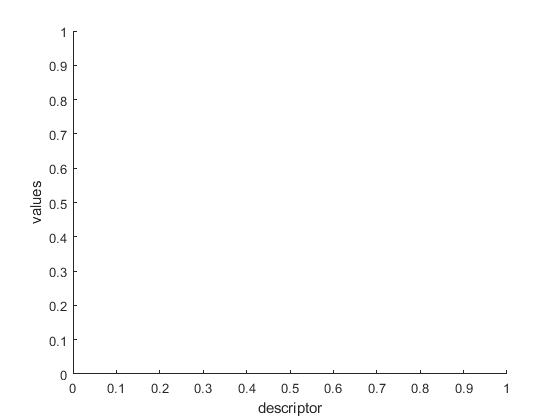

""

=====================================================================================================

## 4. Your first virtual screening exercise

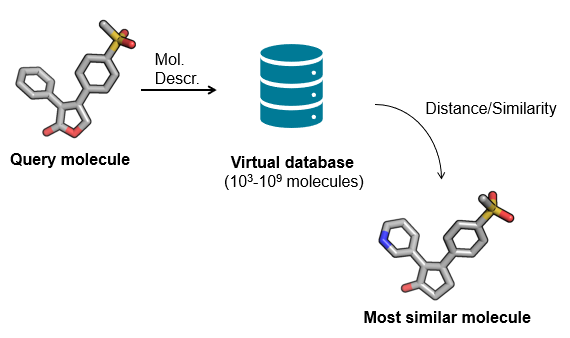

Make sure you save your data and clear the workspace before starting, with the following commands:

`save MyData % or any name you like, really :)`

`clear `

**Exercise 1: Retrieve and import a library of commercial compounds and compute the descriptors**

Usually, for virtual screening you can rely on commercial library of compounds available online, e.g.,:

- Zinc, which contains a catalog of several commercially available compounds [https://zinc.docking.org/substances/subsets/on-demand/](https://zinc.docking.org/substances/subsets/on-demand/) 

- From the provider's website.

In our case, we pre-downloaded a (reduced) library of compounds from [Asinex](http://www.asinex.com/). The library can be found in the current folder, under /data.

You can import the library with the following command:

library = readtable('/data/Commercial_library.csv'); % if you are working with Linux/Mac, change the path notation

You can have a preview of the library with the following line of code (uncomment to make it work)

%head(library)

Finally, you can extract the smiles contained in your table with the following command (uncomment)

%smiles = library.SMILES;

This will provide you with a cell array, containing one SMILES per row. You can now use such array for the following steps of the exercise

**Exercise 2: **compute the molecular descriptors for your library

Often, molecular descriptors are computed starting from a big set of molecule identifiers (e.g., SMILES strings). The descriptors are then arranged in a table with as many rows as the number of molecules (*n*) and as many columns as the number of descriptors (*p*).

In the following rows, construct a code that runs over the *n *SMILES strings contained in "smiles", and returns a matrix **X **(*n* x *p*) containing the output descriptors of the code you previously constructructed ([compute_count_descriptors.m](matlab:open('compute_count_descriptors.m')))

X = []; % empty matrix
for i = 1 : numel(smiles) % runs over the smiles strings
    % complete the code here
    
end

You can convert your data into a more compact format, the so-called MATLAB tables. Tables contain different types of objects, along with their labels. More information can be found here. [https://nl.mathworks.com/help/matlab/tables.html](https://nl.mathworks.com/help/matlab/tables.html)

X_table = array2table(X);
X_table.Properties.VariableNames = labels; % assigns the labels to the descriptors

You can view your table (X_table) within the live editor (if available for your MATLAB version)

X_table

**Exercise 3:** Analysis of your library

You can also use the data you obtained to quickly analyze your data, e.g.:

figure
boxplot(X,'Labels',labels)
xlabel('descriptor')
ylabel('values')

By using the X matrix you obtained, provide an answer to the following questions:

1. What is the most frequent type of atom present in the dataset (based on your descriptors), on average?

2. How many Cl atoms are, on average, possessed by the dataset molecules?

3. What is the maximum number of nitrogen atoms contained by a molecule? 

You can now save your data in the current folder under the name "myData2" (or any other name you like) ;) with the following code:

`save myData2`

#### **Exercise 4: **Retrieve a known drug you want to use as a template molecule

Usually, molecules with one or more desired properties are used as template for virtual screening. This is done following the principle that similar molecules should ideally possess similar properties.

In this exercise, we will use the drug** Acalabrutinib** as a template.

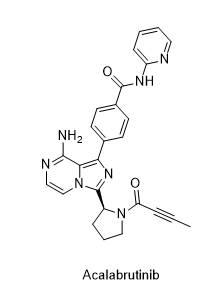

To retrieve the SMILES string of your template, go to DrugBank (https://go.drugbank.com/), and search by compound name.

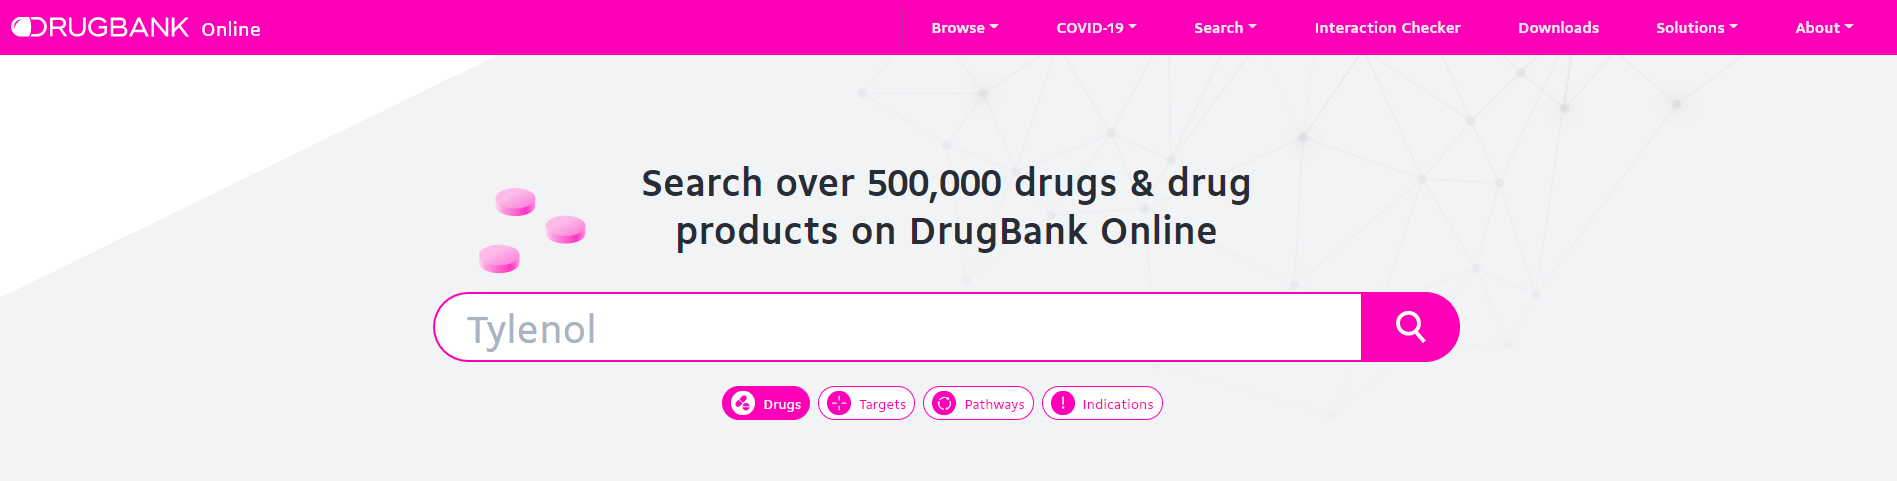

Once you have found your template molecule, you can search for its SMILES strings, and use it to compute the array of molecular descriptors (using the code you previously developed).

Compute your descriptors below

descriptors_template = []

#### **Exercise 5: Perform a virtual screening**

A virtual screening can be divided into several steps.

1. Compute the distance between your template molecule and all of the library molecules

Food for thought

- have a look again at your previous boxplots. Have you considered scaling? Why?

- Do you have a preference for one of the distances we have seen previously? Why?

2. Find the closest compound to the chosen template (paracetamol), based on the previously computed distance

What compound is it? (You can visualize the molecules from their SMILES following this link [http://hulab.rxnfinder.org/smi2img/).](http://hulab.rxnfinder.org/smi2img/).)

Keep track of your top-ranking compound (SMILES) here

""

Can you understand why this was selected, based on the molecular descriptors you used? Does this seem reasonable?